clc
clear

x = [4.16548,4.14432,4.42634,4.410669,4.33221]

x =     4.1655    4.1443    4.4263    4.4107    4.3322


y= [-1.22818,-1.22264,-1.30806,-1.31377,-1.3363]

y =    -1.2282   -1.2226   -1.3081   -1.3138   -1.3363


z = [0.162028,0.155804,0.160105,0.148515,0.0581292]

z =     0.1620    0.1558    0.1601    0.1485    0.0581


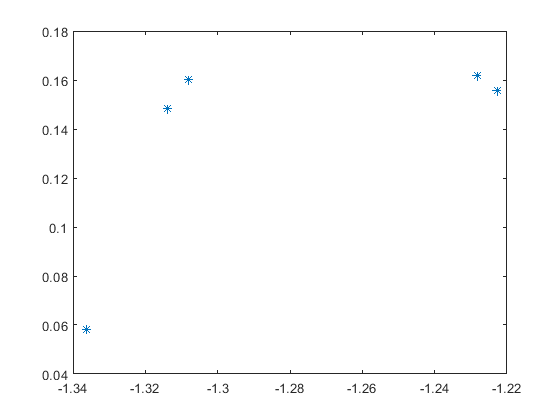

plot(y,z,"*")

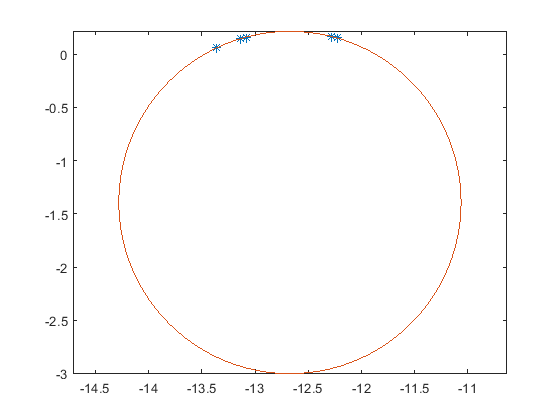

y = y.*10;
z = z;
% 绘制点
figure;
plot(y, z, '*');
axis equal;
hold on;
% 计算圆的参数
[yc, zc, r] = CircleFit(y, z);

% 绘制拟合圆
theta = linspace(0, 2*pi, 100);
circle_y = yc + r * cos(theta);
circle_z = zc + r * sin(theta);
plot(circle_y, circle_z, '-');
hold off;


% 输出圆心和半径
fprintf('圆心: (%.5f, %.5f)\n', yc, zc);

圆心: (-12.67226, -1.39362)


fprintf('半径: %.5f\n', r);

半径: 1.60825


function [x0, y0, R] = CircleFit(y, z)
% 圆的一般方程形式 x^2 + y^2 + a*x + b*y + c = 0
% 求解 a b c 即可
n = length(y);
A = [y(:), z(:), ones(size(y(:)))];
b = -(y(:).^2 + z(:).^2);
x = A\b;
a = x(1);
b = x(2);
c = x(3);
% 圆心、半径
x0 = -a/2;
y0 = -b/2;
R = sqrt((a^2 + b^2) / 4 - c);
end